# File Name: Segmentation_01_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

Create two concentric spheres and combine them into a point cloud.

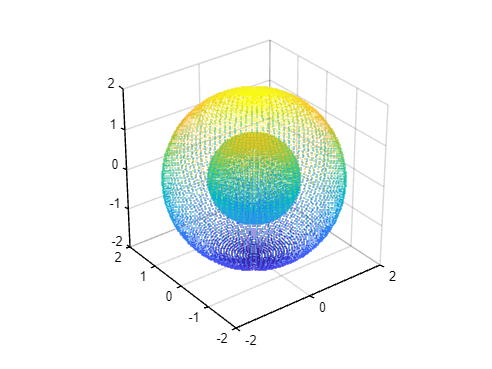

[X,Y,Z] = sphere(100);
loc1 = [X(:),Y(:),Z(:)];
loc2 = 2*loc1;
ptCloud = pointCloud([loc1;loc2]);

pcshow(ptCloud)
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])

Set the minimum Euclidean distance between clusters.

minDistance = 0.5;

%%%%%%%%%% TODO %%%%%%%%%%
% Segment the point cloud.
[labels,numClusters] = pcsegdist(ptCloud,minDistance);

Plot the labeled results. The points are grouped into two clusters.

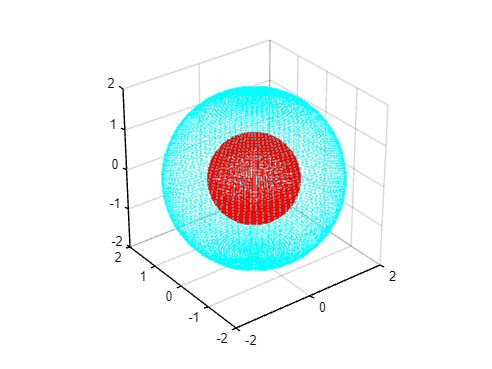

pcshow(ptCloud.Location,labels)
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])

colormap(hsv(numClusters))